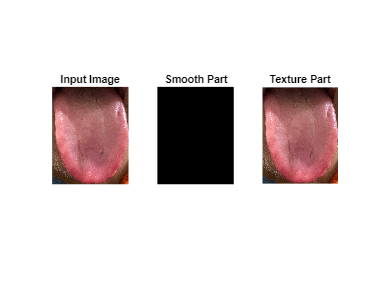

%function [rgbImage_smoothed, rgb_Textured]=divide_into_Smoothed(rgbImage)
close all;
rgbImage=imread('0CA41A93-47F3-40CD-9479-8FB4CCFED190 - vinay kumar.jpeg'); %input image
%===============================================================================
[rows, columns, numberOfColorBands] = size(rgbImage);
% Display the original color image.
subplot(1, 3, 1);
imshow(rgbImage);
title('Input Image');
% Extract the individual red, green, and blue color channels.
redChannel = rgbImage(:, :, 1);
greenChannel = rgbImage(:, :, 2);
blueChannel = rgbImage(:, :, 3);
% Take the stdfilt of the green channel
filteredImage = stdfilt(double(greenChannel), ones(9));
smoothAreas = filteredImage < 2;
smoothAreas = bwareaopen(smoothAreas,round(rows*columns*0.005)); %Remove small regions 
smoothAreas=~smoothAreas;
smoothAreas = bwareaopen(smoothAreas,round(rows*columns*0.005)); %Remove small regions 
smoothAreas=~smoothAreas;
mask3=repmat(smoothAreas, [1,1,3]);% create 3 channel mask
rgbImage_smoothed=rgbImage;
rgb_Textured=rgbImage;
rgbImage_smoothed(~mask3) = 0;
rgb_Textured(mask3) =0;
% Display the image.
subplot(1, 3, 2);
imshow(rgbImage_smoothed, []);
title('Smooth Part');
% Display the image.
subplot(1, 3, 3);
imshow(rgb_Textured, []);
title('Texture Part');

%end %end i